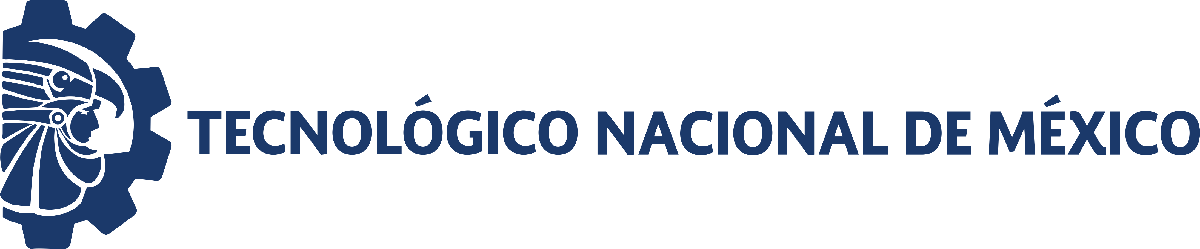                                 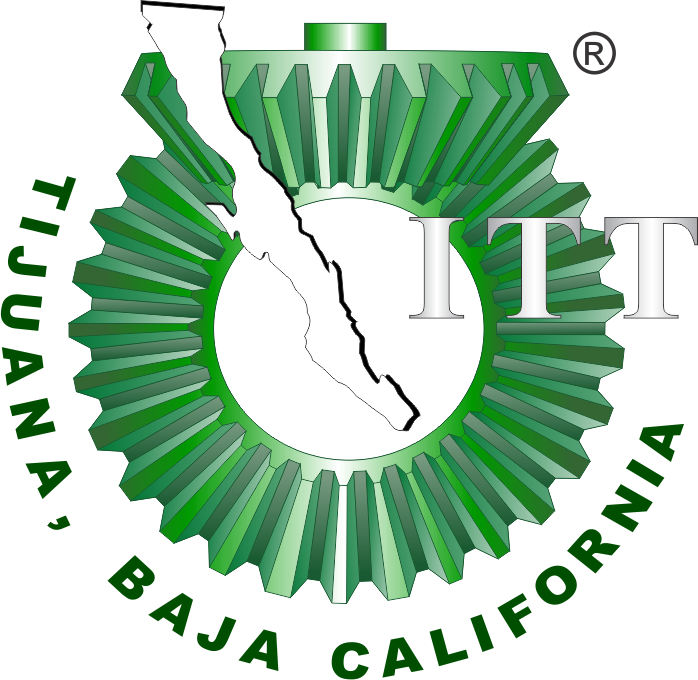

# Práctica 4: Regeneracion de globulos rojos

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

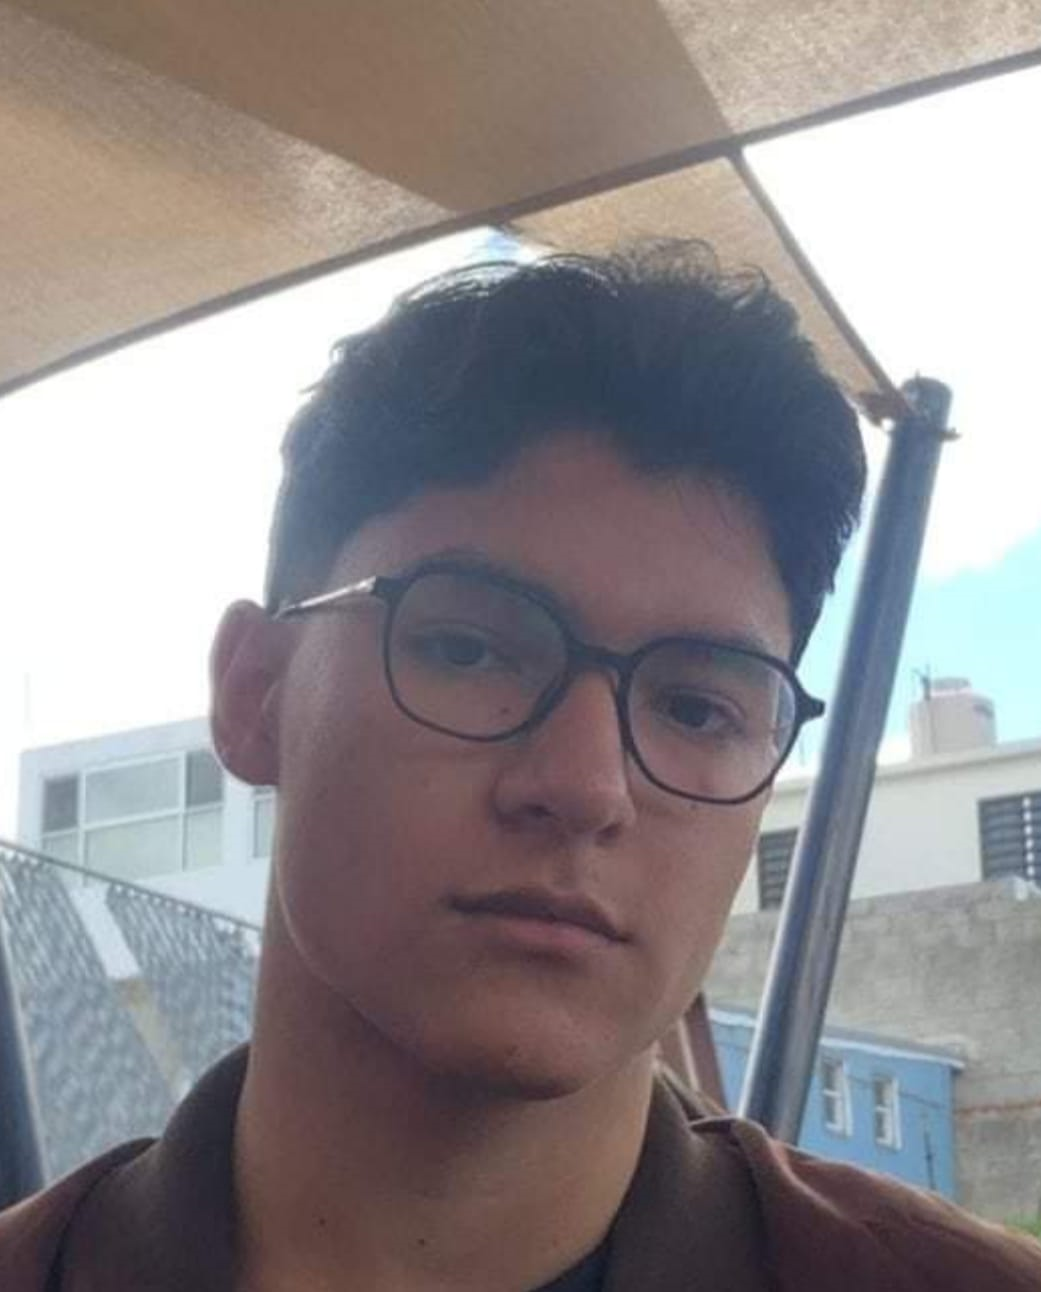

Nombre del alumno: Avila Sanchez German Emmanuel

Número de control: 22212250

Correo institucional: l22212250**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = 180; %Tiempo de la simulacion en dias
dt = 1E-3; %Intervalo de integracion para el metodo de solucion por diferencias finitas
n = round(tend/dt); %Cantidad de iteraciones para el metodo numerico

%Condiciones iniciales base para cada paciente
x1_0 = 59; x2_0 = 44; x3_0 = 855;

%Parametros particulares para cada paciente
gamma = [0.769; 0.388; 0.510; 0.590; 0.262; 0.324; 0.356; 0.089; 0.243; 0.057];
beta = [1.650; 0.867; 1.617; 2.615; 1.518; 2.676; 0.891; 2.557; 0.925; 0.879];

seed = 22212250; %Semilla para asegurar reproducibilidad
rng(seed, 'twister')
%Intervalo de las condiciones iniciales
xmin = 0.99; xmax = 1.01;
interval = xmin + (xmax - xmin).*rand(numel(gamma),1);

%Condiciones iniciales para cada paciente
x1_0 = x1_0*interval; disp('x1(0) = '); disp(x1_0');...
x2_0 = x2_0*interval; disp('x2(0) = '); disp(x2_0');...
x3_0 = x3_0*interval; disp('x3(0) = '); disp(x3_0');

x1(0) = 
   58.9358   58.7360   58.6585   58.7452   58.6488   58.9605   58.6768   59.3005   58.8372   58.7810



x2(0) = 
   43.9521   43.8032   43.7453   43.8100   43.7381   43.9706   43.7590   44.2241   43.8786   43.8367



x3(0) = 
  854.0701  851.1749  850.0510  851.3074  849.9107  854.4281  850.3164  859.3548  852.6404  851.8258



## Caso: Sin transfusion sanguinea [u(t) = 0]

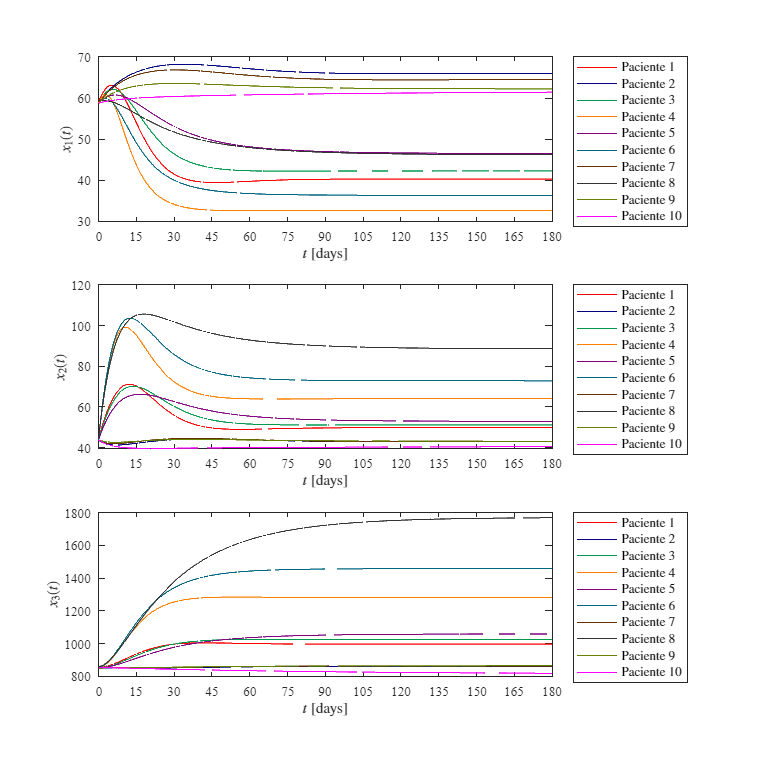

u = zeros(n+1,1); %no hay transfusion
fig = 1;
for i =1:10
    [t,x1,x2,x3] = system(x1_0(i),x2_0(i),x3_0(i),beta(i),gamma(i),u,dt,tend);
    plotdata(t,x1,x2,x3,fig)
end

## Caso: Con transfusion sanguinea [u(t) = 0]

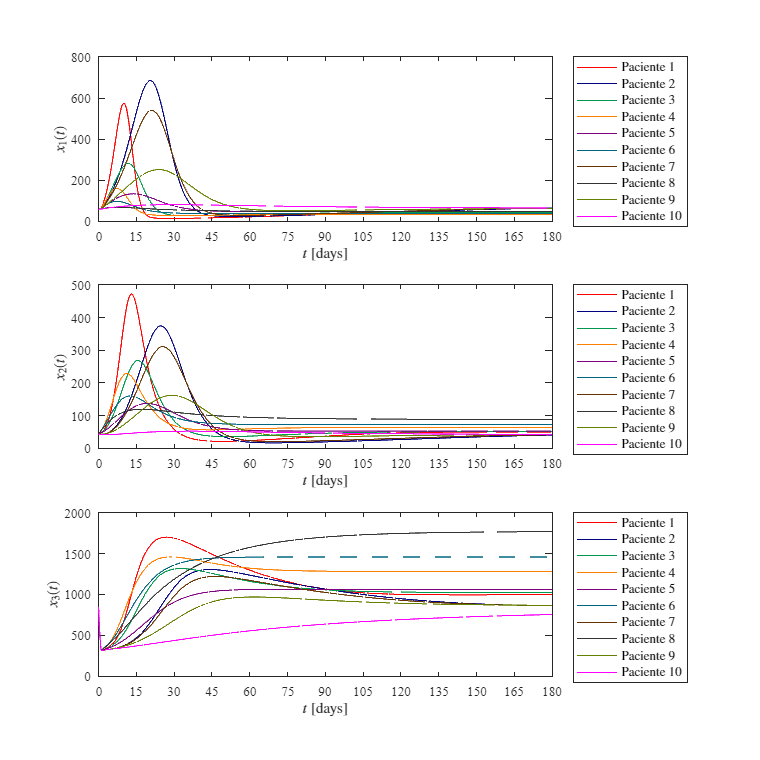

u = zeros(n+1,1); u(1: round( 1/dt)) = 1;
fig = 2; close all
for i = 1:numel(gamma)
     [t,x1,x2,x3] = system(x1_0(i),x2_0(i),x3_0(i),beta(i),gamma(i),u,dt,tend);
     plotdata(t,x1,x2,x3,fig)
end 

## Función: Modelo matematico


$${\dot{x} }_1 =\beta \left(X_0 -k_1 x_1 \right)+\frac{\gamma \left(\mathrm{Base}-x_3 \right)\left(1-u\left(t\right)x_1 \right)}{\mathrm{Base}}$$



$${\dot{x} }_2 =\beta \left(k_1 x_1 -k_2 x_2 \right)$$



$${\dot{x} }_3 =\beta \left(k_2 x_2 -\alpha x_3 \right)-$$

$$u\left(t\right)x_3$$


function[t,x1,x2,x3] = system(x1_0,x2_0,x3_0,beta,gamma,u,dt,tend)
    Base = 885.42; X0 = 7.3785; k1 = 0.125; k2 = 0.1667; alpha = 0.00833;
    t = (0:dt:tend)';
    n = round (tend/dt);
    x1 = zeros(n+1,1);x1(1) = x1_0;
    x2 = zeros(n+1,1);x2(1) = x2_0;
    x3 = zeros(n+1,1);x3(1) = x3_0;
    for i = 1:n%metodo de euler(diferencias finitas)
        x1(i+1) = x1(i)+(beta*(X0 - k1*x1(i)) + gamma*(Base - x3(i))*(1 - u(i))*x1(i)/Base)*dt;
        x2(i+1) = x2(i) + (beta* k1*x1(i)- k2*x2(i))*dt;
        x3(i+1) = x3(i) + (beta*(k2*x2(i) - alpha*x3(i)) - u(i)*x3(i))*dt;

    end 
end

## Función: Soluciones en el tiempo

function plotdata(t,x1,x2,x3,fig)
    set(figure(fig),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,20,20])
    
    mycolors = [1.0, 0.0, 0.0;
                0.0, 0.0, 0.5;
                0.0, 0.6, 0.3;
                1.0, 0.5, 0.0;
                0.5, 0.0, 0.5;
                0.0, 0.4, 0.5;
                0.4, 0.2, 0.0;
                0.2, 0.2, 0.2;
                0.4, 0.5, 0.0;
                1.0, 0.0, 1.0];

    legends = {'Paciente 1','Paciente 2','Paciente 3','Paciente 4',...
               'Paciente 5','Paciente 6','Paciente 7','Paciente 8',...
               'Paciente 9','Paciente 10'};

    subplot(3,1,1)
    hold on; grid off; box on; colororder(mycolors)
    plot(t,x1)
    xlabel('$t$ [days]','Interpreter','latex','FontSize',10)
    ylabel('$x_1(t)$','Interpreter','latex','FontSize',10)
    xlim([0 180]); xticks(0:15:180)
    L = legend(legends,'Location','eastoutside'); 
    set(L,'Interpreter','latex','FontSize',10);
    set(gca,'FontName','Times New Roman','FontSize',10)

    subplot(3,1,2)
    hold on; grid off; box on; colororder(mycolors)
    plot(t,x2)
    xlabel('$t$ [days]','Interpreter','latex','FontSize',10)
    ylabel('$x_2(t)$','Interpreter','latex','FontSize',10)
    xlim([0 180]); xticks(0:15:180)
    L = legend(legends,'Location','eastoutside');
    set(L,'Interpreter','latex','FontSize',10);
    set(gca,'FontName','Times New Roman','FontSize',10)

    subplot(3,1,3)
    hold on; grid off; box on; colororder(mycolors)
    plot(t,x3)
    xlabel('$t$ [days]','Interpreter','latex','FontSize',10)
    ylabel('$x_3(t)$','Interpreter','latex','FontSize',10)
    xlim([0 180]); xticks(0:15:180)
    L = legend(legends,'Location','eastoutside');
    set(L,'Interpreter','latex','FontSize',10);
    set(gca,'FontName','Times New Roman','FontSize',10)

end




